## Low-Speed Steering Friction Torque between the Tire and Pavement

There is surface contact between the tire and pavement, as shown in Figure

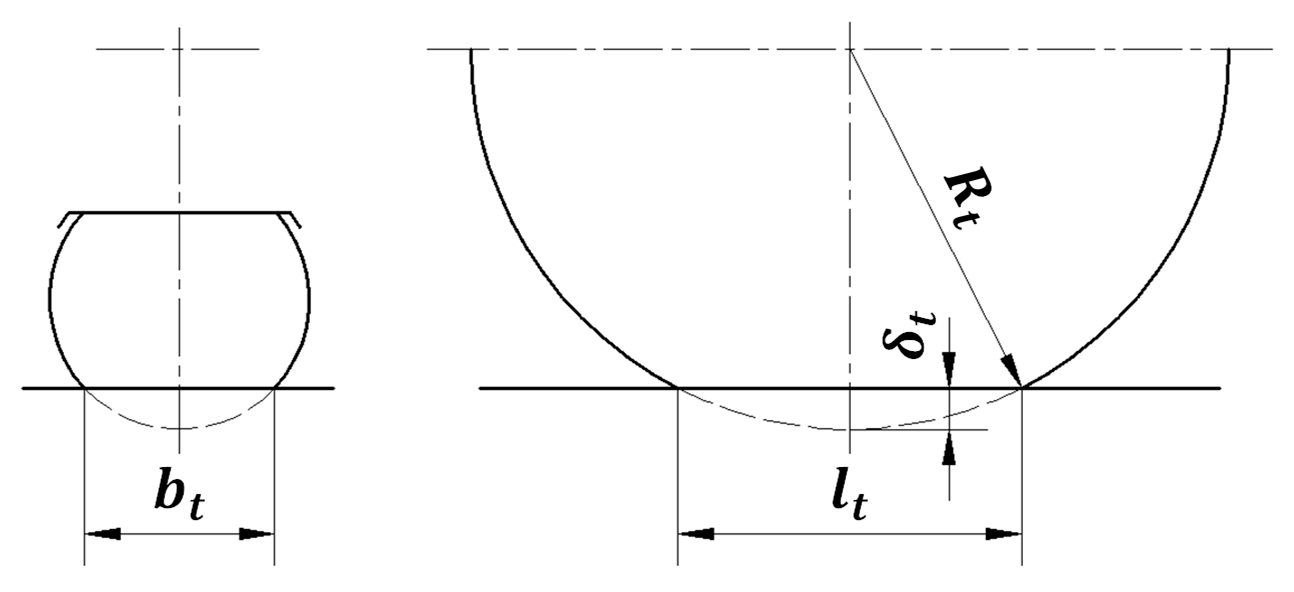

As the load increases, the tire will come into contact with the pavement over the entire width, and the contact region shape will become approximately elliptical and rectangular.

**Shape is considered to be rectangle.**

There is surface contact between the tire and pavement, as shown in Figure 4. Where **dt** is the deformation or subsidence of the tire, **lt** and **bt** are respectively the length and width of the tire/pavement contact region. The values of **dt**, **lt** and **bt** can be calculated by the following empirical formulas.

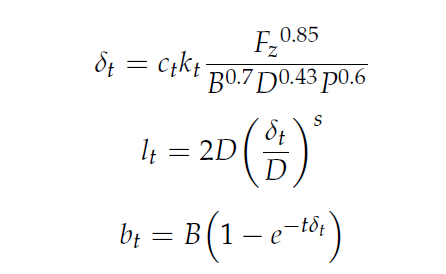

% Coefficients.

ct = 1.15; % For Bias or 1.5 for radial
B = 17.78; % Width of the tire in cm
kt = 0.015*B + 0.42;
Fz = 60; % Vertical Load on the tire in unit 10 N.
D = 292.12; % Diameter in cm
P = 34.4738; % Pressure in unit kPa
s = 0.557;
t = 122.7

t = 122.7000

e = 2.71828;
c = 2 % kingpin offset in cm

c = 2

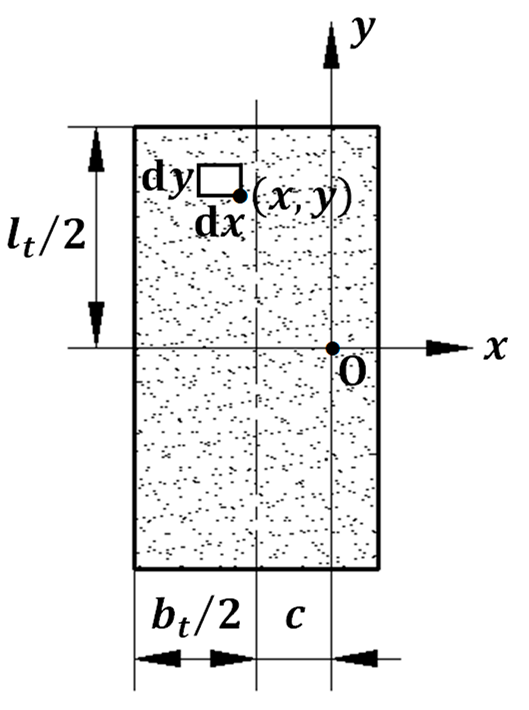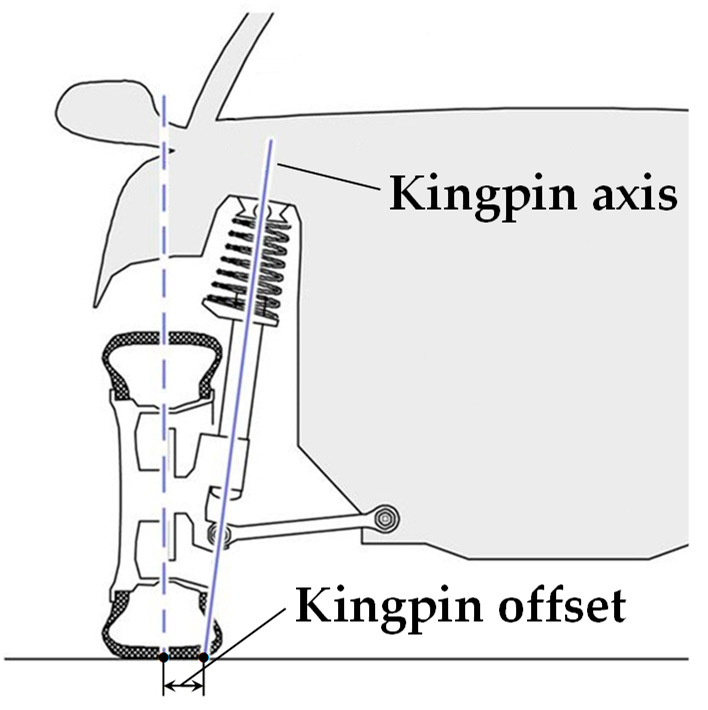


% Formulas:

dt = ct*kt*((Fz^0.85)/((B^0.7)*(D^0.43)*(P^0.6)));
lt = 2*D*(dt/D)^s;
bt = B*(1- e^(-t*dt));


**Now, Low Speed steering friction torque can be computed by:**

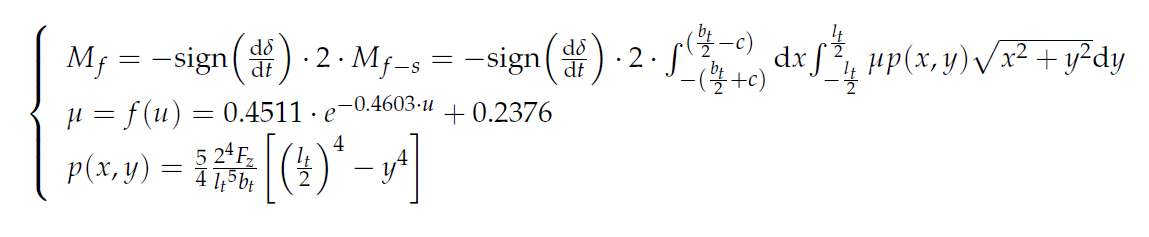

u = 2 % turning speed in km/h

u = 2

mu = 0.4511 * e^(-0.4603*u) + 0.2376;
p = @(y) (((5)*(16)*(Fz))/(4* lt^5 * bt))* ((lt/2)^4 - y.^4);
% Mf = @(x,y) 2*mu*p(y)*sqrt(x.*x + y.*y);
Mf = @(x,y) 2*mu.*p(y).*sqrt(x.*x + y.*y);


friction_torque = quad2d(Mf,6.7771, -10.7771, 1.9288, -1.9288);